% clear all;
% close all;

path_opt_table= readtable('path_opt_rrc.csv');

s_opt_table= readtable('spline_opt_rrc.csv');


london_outer_table=readtable('rrc_outer.csv');

london_inner_table=readtable('rrc_inner.csv');


xy_ref= [path_opt_table.x_Path_x, path_opt_table.path_y];
s_ref= s_opt_table.x_Ds;

state_init= [xy_ref(1, 1), xy_ref(1,2) , 0.0, 0.0];
u_steer= deg2rad([-15:0.3:15]);
dt= 0.001;
dsteer= dt*deg2rad(15/0.9);

s_predict= 3.3; 
s_run= 1296;

u_hist= [];
states_hist=[];
num_iter_hist=[];
v_last= 0;
steer_last= 0;

figure();

for i= 2:s_run
    ds= s_ref(i);
    
    if i< 100
        ds= s_ref(i)*0.98;
    elseif i>=100 && i< 120
        ds= s_ref(i)*1.05;
    elseif i>=120 && i<170
        ds= s_ref(i)*0.98;
    elseif i>=280 && i<=290
        ds= s_ref(i)*1.03;
    elseif i>= 560 && i<580
        ds= s_ref(i)*1.05;
    elseif i>=725 && i<=745
        ds= s_ref(i)*0.98;
    elseif i>=860 && i<=880
        ds= s_ref(i)*1.05;
    elseif i>=960 && i<=990
        ds= s_ref(i)*0.98;
    elseif i>=1100 && i<=1130
        ds= s_ref(i)*0.98;
    elseif i>1130 && i<=1160
        ds= s_ref(i)*1.05;
    elseif i>1185 && i<=1210
        ds= s_ref(i)*0.96;
    else
        ds= s_ref(i);
    end
    
    state0= state_init;
    
    ref_devi= (xy_ref(i,2)- xy_ref(i-1,2))/(xy_ref(i,1)- xy_ref(i-1,1));
    dist_err_list=[];
    cord_err_list=[];
    devi_err_list=[];
    
    % generate path for each steer angle
    for j= 1:length(u_steer)
        
        [states_predict, u_predict, iter_predict]= StatesUpdate(state_init, dt, u_steer(j), dsteer, v_last, steer_last, s_predict);
        states_predict= [state_init; states_predict];
        
        path_devi= (states_predict(end, 2)- state0(2))/((states_predict(end,1)- state0(1)));
        devi_err= abs(path_devi- ref_devi);
        devi_err_list= [devi_err_list; devi_err];
        

%         dist_err= (states_predict(:,1)- xy_ref(i, 1)).^2+ (states_predict(:,2)- xy_ref(i, 2)).^2;
%         dist_err_sum= sum(dist_err);
%         dist_err_list= [dist_err_list; dist_err_sum];
        
        
%         plot(states_predict(:,1), states_predict(:,2), "Color", "blue");
%         set(gca,'LooseInset',get(gca,'TightInset'))
%         % set(gca,'position',[0 0 1 1]);
%         hold on;
    end
    
    steer_id= find(devi_err_list== min(devi_err_list));
    %steer_id= find(dist_err_list== min(dist_err_list));
    
    [states_execute, u_execute, num_iter, steer_vector]= StatesUpdate(state0, dt, u_steer(steer_id), dsteer, v_last, steer_last, ds);
    
%     plot(states_execute(:,1), states_execute(:,2), "Color", 'red',"LineWidth", 2.0);
%     hold on
%     plot(xy_ref(1:s_run, 1), xy_ref(1:s_run, 2), 'linewidth', 2.0, "Color", 'green', "LineStyle","--");
%     hold on
%     plot(states_execute(end,1), states_execute(end,2), "Color", 'black','Marker',"o");
%     xlabel("x(m)")
%     ylabel("y(m)")
    

    u_hist= [u_hist; u_execute];
    states_hist= [states_hist; states_execute];
    num_iter_hist= [num_iter_hist; num_iter];
    
    state_init= states_execute(end,:);
    v_last= states_execute(end-1, 4);
    steer_last= u_execute(end,3);
end

** plot path outline**

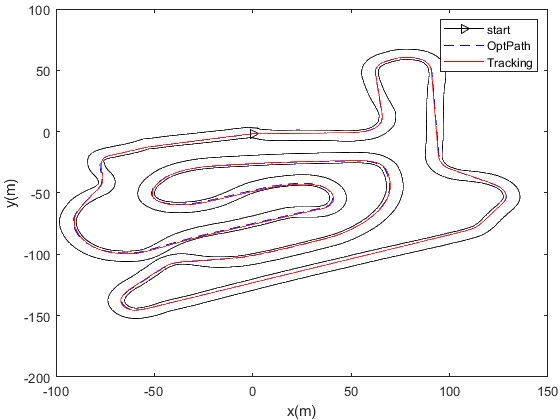

plot_num= 1:s_run;
% close all;

figure();
plot(xy_ref(1,1), xy_ref(1,2), "Color", 'black', 'linewidth', 0.5, "LineStyle","-", "Marker",">");
hold on;
plot(xy_ref(plot_num, 1), xy_ref(plot_num, 2), 'linewidth', 0.5, "Color", 'blue', "LineStyle","--");
hold on;
plot(states_hist(:,1), states_hist(:,2), 'linewidth', 0.5, "Color", 'red');
hold on;
plot(london_outer_table.x_Outer_x, london_outer_table.outer_y, 'black', 'LineWidth', 0.7)
hold on;
plot(london_inner_table.x_Inner_x, london_inner_table.inner_y, 'black', 'LineWidth', 0.7)
hold off
legend('start', 'OptPath', 'Tracking');
xlabel("x(m)")
ylabel("y(m)")
set(gca,'LooseInset',get(gca,'TightInset'))

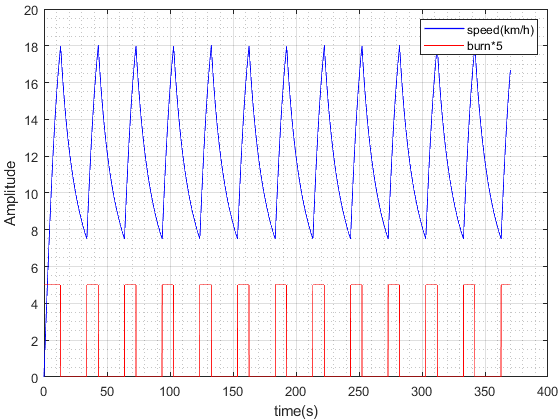

t_num= dt.* [1:1:length(u_hist)];

figure();
plot(t_num ,states_hist(:,4)*3.6, 'linewidth', 1.0, "Color", 'blue');
hold on;
plot(t_num, u_hist(:,2)*5, 'red', 'LineWidth', 0.7);
hold off;
xlabel("time(s)")
ylabel("Amplitude")
grid on; grid minor;
set(gca,'LooseInset',get(gca,'TightInset'))
legend("speed(km/h)", "burn*5");

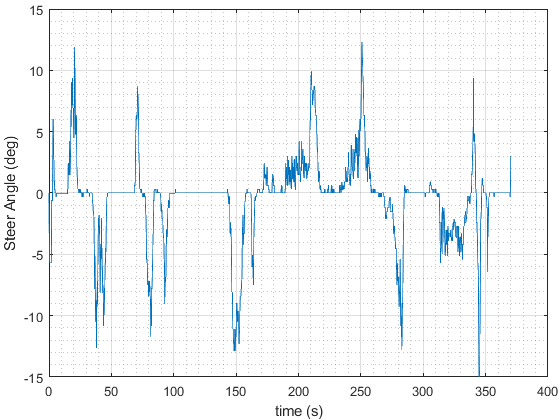


% figure();
% plot(t_num ,u_hist(:,2), 'linewidth', 1.0, "Color", 'black');
% grid on; grid minor;
% xlabel("time (s)")
% ylabel("Burn Signal")
% 
% set(gca,'LooseInset',get(gca,'TightInset'))

figure;
plot(t_num, rad2deg(u_hist(:,3)), 'LineWidth', 0.7);
grid on; grid minor;
xlabel("time (s)")
ylabel("Steer Angle (deg)")

set(gca,'LooseInset',get(gca,'TightInset'))


% subplot(3,1,3)
% plot(t_num , u_hist(:,1), 'linewidth', 1.0, "Color", 'red');
% xlabel("time (s)")
% ylabel("Normalized f_{drive}")

**plot steer input vs distance**

% dist_num= 0: s_run/length(u_hist):s_run;
% 
% n= length(dist_num(1:100:end));
% 
% figure();
% plot(dist_num(1:100:end-1) ,states_hist(1:100:end,4)*3.6, 'linewidth', 1.0, "Color", 'blue');
% hold on;
% plot(dist_num(1:100:end-1), 25.*ones(1, n), 'red', 'LineWidth', 1.0);
% hold off;
% xlabel("distance(m)")
% ylabel("Speed (km/h)")
% grid on; grid minor;
% ylim([0, 26])
% legend("speed", "speed limit")
% set(gca,'LooseInset',get(gca,'TightInset'))

% figure;
% plot(dist_num(1:100:end-1), rad2deg(u_hist(1:100:end,3)), 'LineWidth', 0.7);
% grid on; grid minor;
% xlabel("distance(m)")
% ylabel("Steer Angle (deg)")
% set(gca,'LooseInset',get(gca,'TightInset'))
